# 3. Implement LQR and PID Controller for Balancing Control

## 3.1 Overview

For didactic reasons we walk through the classic way of implementing an LQR controller, that uses the linearization of the equation of motion. In principle it is possible to linearize a Simulink model and to optimize the controller gains using several apps. However, the resulting linearized model might not always be the same as if derived from first principles and thus might cause some confusion. This is especially the case for systems that are inherently unstable such as this balancing robot.

Hence we will use the equations of motion using estimated physical parameters. This should give a first draft of a working controller that we can refine at a later stage.

## 3.2 State space representation of the system

For this we make use of the equations of motion of the robot that can be derived using Lagrangian mechanics [[1](matlab:open('..\Specs\EduBal_paper.pdf'))]. Basically, one considers an equation for the board and one for the wheels/drive.

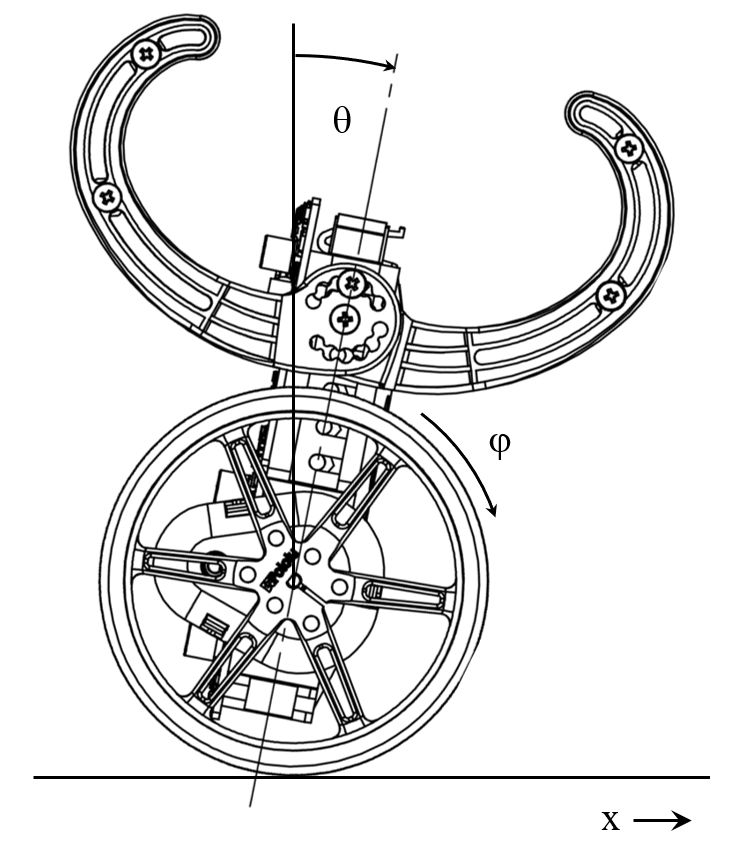

(1)    $rlm\ddot{\theta}\cos(\theta)+rm\ddot{p}-rlm\sin(\theta)\dot\theta^2=T$

(2)    $2l^2m\ddot\theta+lm\ddot{p}\cos(\theta)-glm\sin(\theta)=-T$

where $p=r(\varphi+\theta)$is the position of the robot and $T$ are the motor torques.

For further analysis this system is linearized about the equilibrium point using the approximations:

$\cos(\theta)\approx 1$    $\sin(\theta)\approx 0$ and $\dot\theta^2\approx 0$

(3)    $rlm\ddot\theta+rm\ddot p=-2l^2m\ddot\theta - lm\ddot p + glm \theta$

#### Note on estimation of physical parameters

The model above uses a simplified model of the robot (point masses instead of bodies). To get the corresponding parameters we have to approximately map the body geometry to this representation.

The mass of the robot including the battery pack is about 0.37 kg. Assuming cuboid dimensions of the main body with 13cm x 8cm x 2 cm (h x w x t) we can calculate its density to be $\rho=\frac{m}{hwt}=1.778 \, \mathrm{\frac{t}{m^3}}$.

The wheel axis is mounted at a height of 3cm (cuboid frame) and the center of mass is $d=3.5\,\mathrm{cm}$ above this axis. To get the right mechanical behavior we have to calculate the moment of inertia of the robot body.

The inertial moment of the cuboid around a centered axis is $I_c=\frac{1}{12}m(h^2+t^2)=0.53\cdot 10^{-3} \, \mathrm{kg\, m^2}$. According to the "Satz of Steiner" we can calculate the moment about the wheel axis  as$I=I_c+md^2=2.1\cdot10^{-3} \, \mathrm{kg\, m^2}$.

Thus to get this aligned with the model below, we could describe the rotational behavior of the robot body using a single point mass that would be $r=\sqrt{I/m}=7.5 \, \mathrm{cm}$ above the wheel axis.

m=0.370;
l=0.075; %0.079793%determined by pendulum experiment %former values 0.032, 0.035;
lm=l*m; %lm=0.032*0.377
r=0.0405;

## 3.3 Linearization of the Equations of Motion

Rearranging for $\ddot{\theta}$ and taking into account that we should also model the dynamics of the motor control loop with


$$\ddot{\varphi}=-\frac{1}{t_{EM}}\dot{\varphi}+\frac{K}{t_{EM}}\dot{\varphi}_{ref}$$
 

we can rewrite the dynamics as a system of differential equations with the state vector $\mathbf{x}=(\varphi,\dot{\varphi},\theta,\dot{\theta})^T$. Using the small angle approximation and linearizing around the operating point (0,0,0,0) we can represent the modal as a linear state space system [[1](matlab:open('..\Specs\EduBal_paper.pdf'))]


$$\mathbf{\dot{x}=Ax+Bu}$$



$$\mathbf{y=Cx}$$


$\mathbf{A}=\left(\begin{array}{c c c} 0 &1 & 0 & 0 \\ 0 & -\frac{1}{t_{EM} & 0 & 0 \\ 0 & 0 & 0 & 1 \\ 0 & \frac{lm+rm}{t_{EM}\eta} & \frac{glm}{r\eta} \end{array}\right)$,    $\mathbf{B}=\left(\begin{array}{c} 0 \\ \frac{K}{t_{EM}} \\ 0 \\ -\frac{lm + rm}{t_{EM}\eta} \end{array}\right)$,    $\mathbf{C}=\left(\begin{array}{c c c c} r & 0 & r & 0 \\ 0 & 0 & 1 & 0 \end{array}\right)$

where $u=\dot{\varphi}_{ref}$ the input speed, $\mathbf{y}=(p,\theta)^T$ the output and $\eta=2ml+mr+\frac{2ml^2}{r}$.

rm=r*m; %rm=0.0405*0.377
K=1;

tem=0.1 %initial guess / this is the time we used for the speed controllers

tem = 0.1000


eta=2*lm+rm+(2*m*l^2/r);

The matrix $\mathrm{A}$ has positive eigenvalues, indicating that the system is unstable.

%calculate the controllability matrix
A31=(lm+rm)/(tem*eta);
A32=9.81*lm/(r*eta);
A=[-1/tem, 0, 0; 0, 0, 1;A31, A32, 0];
B=[1/tem;0;-A31];

## 3.4 Solving the Riccati Equation for the LQR Balancing Controller

The full state vector $\mathbf{x}=(\varphi,\dot{\varphi},\theta,\dot{\theta})^T$ includes the wheel position. In order to design a balancing controller we can focus on a three-state linear quadratic regulator that discards the position. The position can then be controlled using an outer loop with a PID. We thus consider the state $\tilde \mathbf{x}$:


$$\mathbf{x}=\left( \begin{array}{c} \dot\varphi \\ \theta - \theta_{ref} \\ \dot \theta \end{array} \right)$$


To get the lqr gains we have to solve the Riccati equation,


$$J(u)=\int_0^{\infty} (x^TQx+uRu)dt$$


where $Q=\mathrm{diag}(0,1,0)$ and $R=10$ penalize the control error in body angle and actuation energy. This equation can be solved using the `lqr `command.

[K,S,P]=lqr(A,B,diag([0,1,0]),10)

tem = 0.1000

K =    -2.0000  -81.9636  -13.1593


S = 1.0e+03 *

    0.0032    0.1316    0.0211
    0.1316    5.3929    0.8658
    0.0211    0.8658    0.1390


P =    -6.1791
   -6.2788
   -9.9992


We can now use the lqr gains given by $K$ and implement them into our model.

## 3.5 Validate Controller on Digital Twin

We can directly use the gains $K$ to stabilize our robot model. For this we multiply the state vector with the gain and feed this back to the plant input.

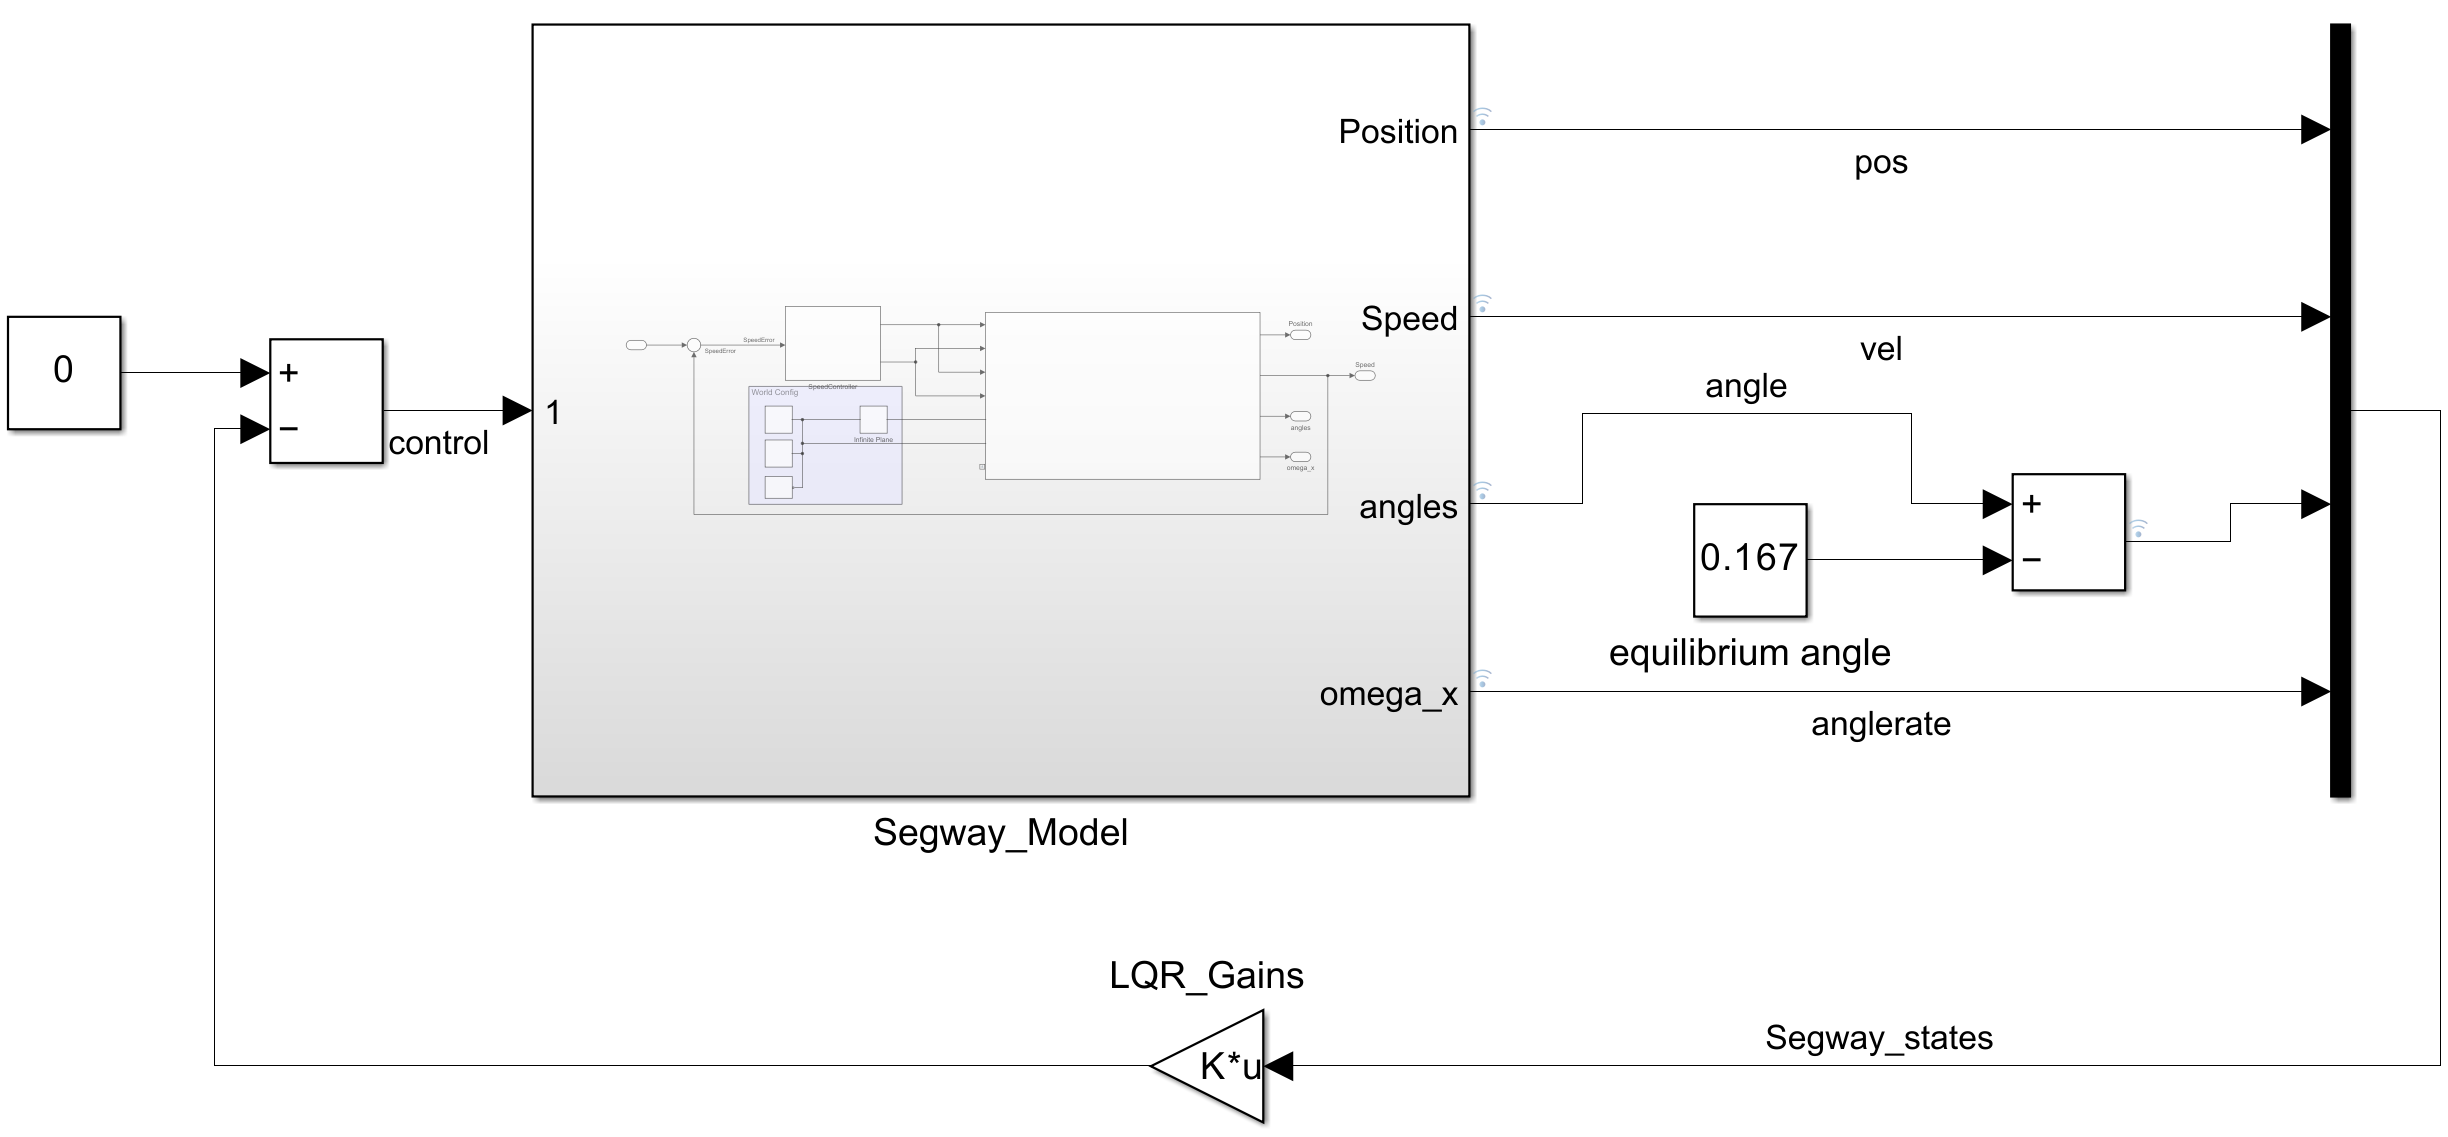

To get a better control on the distance we can remove the LQR gain for the position and implement a PID controller for this signal instead. 

open_system("Ex5_ControlDesign_Draft")
% simulate the model and check the tracking performance...

## References

[1] C.-E. Framing, R. Hedinger, E. S. Iglesias, F.-J. Heeler, and D. Abel, “EduBal: An open balancing robot platform for teaching control and system theory”, *IFAC-PapersOnLine*, Vol. 53, no. 2, 2020.